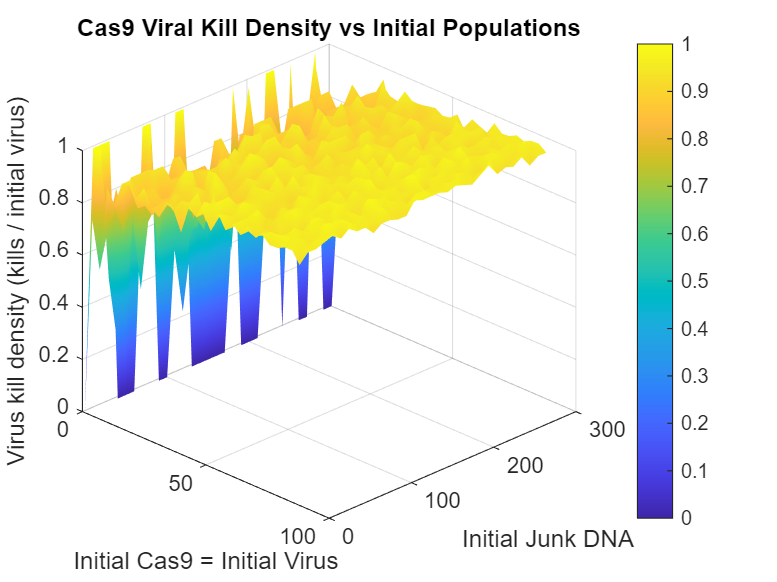

%% Load data
T = readtable('batch_results.txt', 'Delimiter', '\t');

cas9_init   = T.init_cas9_virus;      % = initial Cas9 = initial virus
junk_init   = T.init_junk;            % initial junk DNA
kill_density = T.virus_kill_density;  % virus killed / initial virus

%% Build grids for surface plot
cas9_vals  = unique(cas9_init);   % 1,4,7,...,88  (30 values)
junk_vals  = unique(junk_init);   % 0,10,...,300 (31 values)

% Data are ordered: for each junk level, cas9 runs through all values.
% So reshape kill_density into [nCas9 x nJunk] and transpose.
nCas9 = numel(cas9_vals);
nJunk = numel(junk_vals);

Z = reshape(kill_density, [nCas9, nJunk])';   % size 31 x 30

% Create matching X,Y grids
[CAS9, JUNK] = meshgrid(cas9_vals, junk_vals);

%% 3D surface plot
figure;
surf(CAS9, JUNK, Z);
shading interp;            % smooth color
colormap parula;           % or turbo/hot/etc
colorbar;

xlabel('Initial Cas9 = Initial Virus');
ylabel('Initial Junk DNA');
zlabel('Virus kill density (kills / initial virus)');
title('Cas9 Viral Kill Density vs Initial Populations');

view(45, 30);              % adjust viewing angle as you like